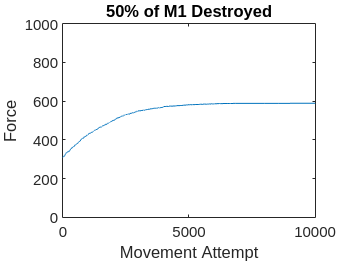

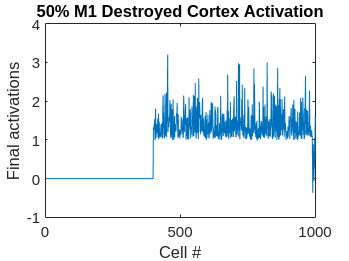

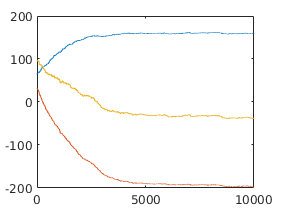

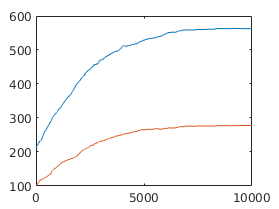

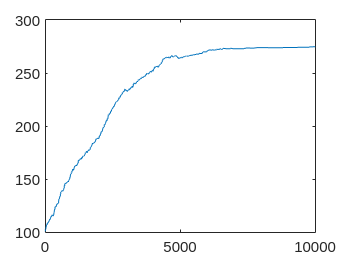

addpath('functions/');

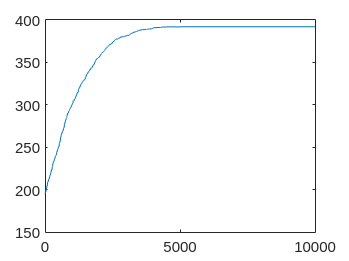

% Creating n Corticalspinal cells
n = 1000; 

% Initalize the base CS cells
% 80% of the n Cortical cells are M1
m1_count = n * 0.8;
m1_destroyed = m1_count * 0.5;
m1_alive = m1_count * 0.5;
m1 = [zeros(1, m1_destroyed), rand(1, m1_alive)];
% 20& of the n Cortical cells are SMA
sma_count = n * 0.2;
sma = rand(1, sma_count);

x_0 = [m1, sma];

% Parameters for zero-mean normal distribution
std_dev = 0.02;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_fi = [ones(1, n)]; 

m1_agonist = randperm(m1_count * 0.99);
m1_x_0 = rand(1, m1_count);
sma_agonist = randperm(sma_count * 0.99);
sma_x_0 = rand(1, sma_count);

% Translating MN pool to force
delta = 1;

f_fs = [];
f_es = [];
sma = [];
m1 = [];
final_forces_m1 = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, m1_count) + mean;
    x_i = m1_x_0 + v_i;

    for i = 1:m1_destroyed
        % Ensure CS M1 cells are destroyed (0)
        x_i(i) = 0;
    end

    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:length(m1_agonist)
        ind = m1_agonist(i);
        s_fi = s_fi + g_fi(x_i(ind), flexor_c_fi(ind));
    end
    f_f = delta * s_fi;

    % Net force
    f_net = f_f;

    if f_net > f_final_net
        f_final_net = f_net;
        m1_x_0 = x_i;
    end

    m1 = [m1, sum(m1_x_0)];
    final_forces_m1 = [final_forces_m1, f_final_net];
end

f_final_net = 0;
final_forces_sma = [];
for trial = 1:max_trials
    v_i = std_dev.*randn(1, sma_count) + mean;
    x_i = sma_x_0 + v_i;

    % Flexor MN Pools translated to force
    s_fi = 0;
    
    for i = 1:length(sma_agonist)
        ind = sma_agonist(i);
        s_fi = s_fi + 0.1 * g_fi(x_i(ind), flexor_c_fi(ind));
    end

    f_f = delta * s_fi;

    % Net force
    f_net = f_f;

    if f_net > f_final_net
        f_final_net = f_net;
        sma_x_0 = x_i;
    end

    sma = [sma, sum(sma_x_0)];
    final_forces_sma = [final_forces_sma, f_final_net];
end

plot(final_forces_m1)

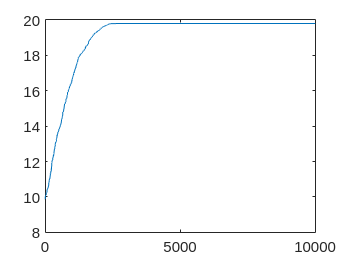

plot(final_forces_sma)

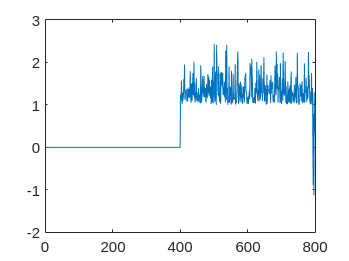

plot(m1_x_0)

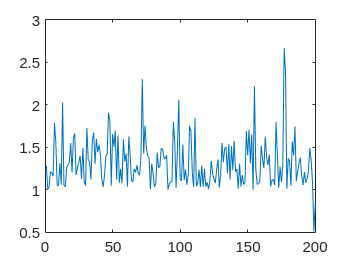

plot(sma_x_0)

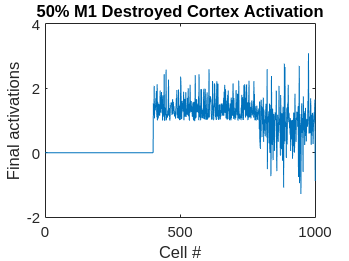

plot(x_0)
%hold on
%plot(10 * ones(1, m1_count))
%hold off
title("50% M1 Destroyed Cortex Activation")
%ylim([0, 15])
ylabel("Final activations")
xlabel("Cell #")

saveas(gcf, 'images/M1Destroyed50Activations.png')

plot([1:10000], f_fs, [1:10000], f_es, [1:10000], f_fs + f_es)

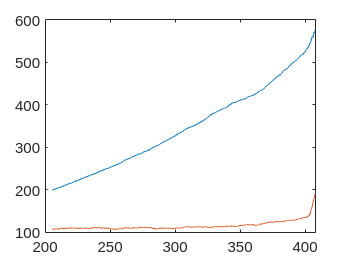

plot(final_forces_m1, sma, final_forces_m1, m1)

plot(m1)

function s = g_fi(c_i, x_i)
    % Positive Saturation Limit
    s = c_i * x_i;
    if c_i > 0 && s > 1
        s = +1;
    end
end

function s = g_ei(c_i, x_i)
    % Negative Saturation Limit
    s = c_i * x_i;
    if c_i < 0 && s < -1
        s = -1;
    end
end